# Робот-манипулятор двухзвенный 

Выполнил: студент группы R4136c, Ларченков Артем

Цель работы: Оптимизация траектории робота с помощью метода роя.


$$reward = -\frac{ t^2}{1+|x| + |y| + |z|}$$


## Open the model with previous (initial) data

Open the open-chain model with settings for jumping behaviour

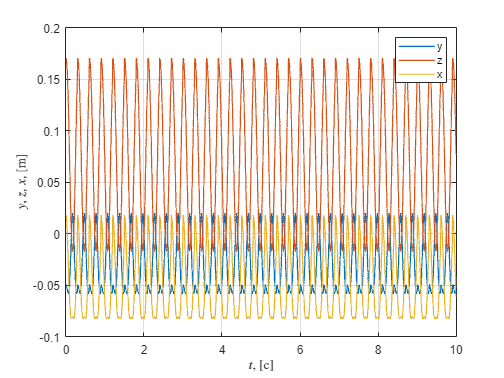

res_1_1 = 'optData_step_1_jump_15May23_2234.mat';
% res_1_2 = 'optData_Ga15May23_2321.mat';
% res_1_1 = 'optData_step_1_jump_1.mat';

load(res_1_2)
parameterss % model parameters
mdlName = 'robott_old'; % main model
open_system(mdlName); % open main model
% jump = 1; run = 0; % option for jumping 
sim_oc_jump = sim(mdlName,'StopTime','10','SrcWorkspace','current');
measBody = get(sim_oc_jump.yout,'measBody').Values;

figure
plot(measBody.X.Time, measBody.X.Data, ...
     measBody.Y.Time, measBody.Y.Data, ...
     measBody.Z.Time, measBody.Z.Data, ...
    'linewidth', 1)
grid on
xlabel('$t$, [c]','Interpreter','latex')
ylabel('$y$, $z$, $x$, [m]','Interpreter','latex')
legend('y','z','x')

## Set optimization

Define the number of end-effector's trajectory points and initial parameters 

numPoints = 2;     
alpha = 0.08; % [rad]
gait_period = 0.40;

Create initial conditions to seed the initial population for optimization.Initial conditions consist 4 points: (2 trajectory points, alpha value, gait period value)

p0 = [zeros(1,numPoints) alpha gait_period]

p0 =          0         0    0.0800    0.4000


## Set optimization options

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

opts = optimoptions('particleswarm');
opts.Display = 'iter';
opts.MaxIterations = 10;

opts.InitialSwarmMatrix = repmat(p0,[numPoints 1]); % Add copies of initial gait 
opts.PlotFcn = @pswplotbestf; % Add progress plot of fitness function
opts.UseParallel = false;

## Set constraints for trajectory points, alpha and gait period

upperBnd = [ 0.185*ones(1,numPoints), ...    % r max
             10*pi/4,...                      % alpha max
             0.50];                           % gait_period max
lowerBnd = [ 0.004*ones(1,numPoints), ...     % r min
             5*pi/4,...                      % alpha min
             0.40];                          % gait_period min

## Run optimization

Here we use the [`ga`](https://www.mathworks.com/help/gads/ga.html) function from Global Optimization Toolbox to optimize the walking gait, with **simulateOpenChainRobot** as the fitness function.

Some initial particle positions are not between bounds lb and ub; PARTICLESWARM
shifted them to satisfy the bounds.    0.0040    0.0040    3.9270    0.4000

    0.0040    0.0040    3.9270    0.4000

    0.0710    0.1830    6.7527    0.4099

    0.1563    0.0161    7.8389    0.4044

    0.1369    0.1740    5.3192    0.4557

    0.1074    0.0073    7.7411    0.4772

    0.0360    0.1278    5.2875    0.4312

    0.1773    0.1459    7.4084    0.4179

    0.0520    0.1007    5.7126    0.4339

    0.1713    0.1643    5.5505    0.4210

    0.0445    0.1667    4.7820    0.4510

    0.0716    0.1173    4.4204    0.4906

    0.0198    0.0290    5.1401    0.4629

    0.1199    0.0434    6.7784    0.4102

    0.0367    0.0370    7.0013    0.4391

    0.0122    0.0116    6.6515    0.4055

    0.1349    0.0234    3.9655    0.4501

    0.0669    0.1156    7.2383    0.4432

    0.1236    0.1741    7.5490    0.4998

    0.0735    0.0682    6.9545    0.4812

    0.1175    0.0783    4.0945    0.4486

   

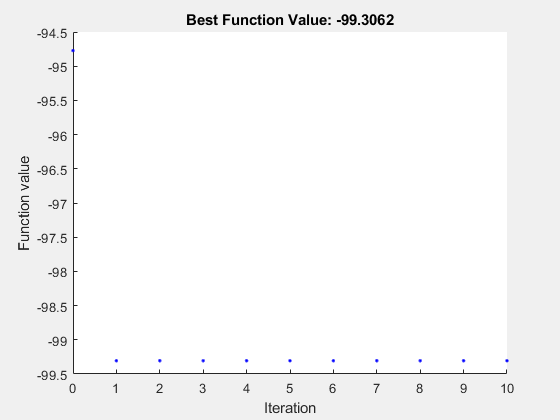

parameters % model parameters
mdlName = 'robott_20201'; % main model

costFcn = @(p)optOpenChainmove(p,mdlName);

[pFinal,reward] = particleswarm(costFcn,numPoints+2,lowerBnd,upperBnd,opts);

disp(['Final reward function value: ' num2str(-reward)])

Final reward function value: 99.3062


## Analyze and save results

r_motion = [pFinal(1:numPoints) pFinal(1)];
alpha   = pFinal(numPoints+1)

alpha = 7.8540

gait_period = pFinal(numPoints+1+1)

gait_period = 0.4732

traj_times  = linspace(0,gait_period,numPoints+1);

Evaluate the trajectory at a few points for visualization

numTrajPoints = 101;
evalTimes = linspace(0,gait_period,numTrajPoints);
spln = createSpline(r_motion,gait_period,evalTimes);
r_der = createSmoothTrajectory(r_motion, gait_period);

Plot the resulting trajectory

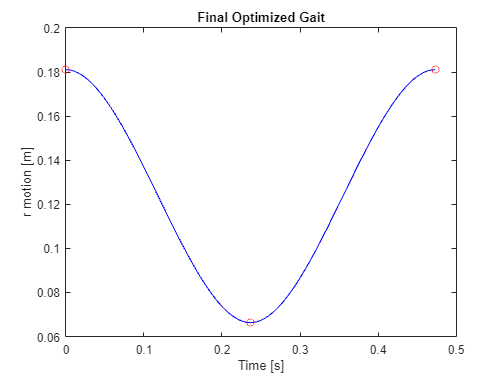

figure
plot(evalTimes,spln(1,:),'b-',traj_times,r_motion,'ro');
title('Final Optimized Gait');
xlabel('Time [s]');
ylabel('r motion [m]');

Save results to a timestamped MAT-file

outFileName = ['optData_Roy' datestr(now,'ddmmmyy_HHMM')];
save(outFileName,'reward','gait_period','traj_times','r_motion','alpha','r_der');

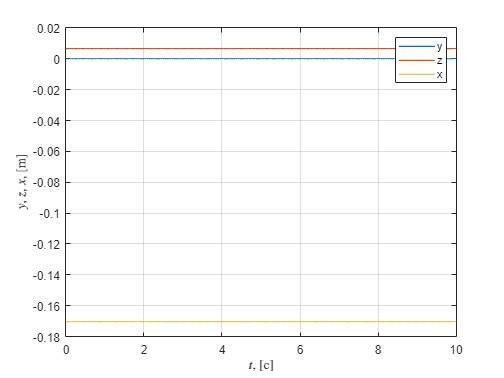

sim_traj = sim(mdlName,'StopTime','10','SrcWorkspace','current');
measBody = get(sim_traj.yout,'measBody').Values;

figure
plot(measBody.Y.Time, measBody.Y.Data, ...
     measBody.Z.Time, measBody.Z.Data, ...
     measBody.X.Time, measBody.X.Data, ...
    'linewidth', 1)
grid on
xlabel('$t$, [c]','Interpreter','latex')
ylabel('$y$, $z$, $x$, [m]','Interpreter','latex')
legend('y','z','x')